%%%
% SPDX-License-Identifier: LGPL-3.0-or-later
% Copyright (c) 2025 Zherui Li
%%%

%%% V5
% read measured data from worksheet
filename = './H-275 3D Simulations/Measured Data.xlsx';
sheets = sheetnames(filename);
lastSheet = sheets{5};
V5_L_Kranion_data = readtable(filename, 'Sheet', lastSheet, 'VariableNamingRule','preserve');

% clean raw data
nRows = height(V5_L_Kranion_data);
rowsToRemove = [];
for k = 3:5:nRows
    rowsToRemove = [rowsToRemove, k:min(k+2, nRows)];
end
V5_L_Kranion_data(rowsToRemove, :) = [];

% extract data into separate arrays
T = V5_L_Kranion_data;
conditions = unique(T{:,1});
varNames = T.Properties.VariableNames(2:14);
meanResults = cell(length(conditions), length(varNames));
stdResults  = cell(length(conditions), length(varNames));
for i = 1:length(conditions)
    cond = conditions{i};
    rows = strcmp(T{:,1}, cond);

    for j = 1:length(varNames)
        currentVar = varNames{j};
        dataMatrix = T{rows, currentVar};
        dataMatrix = dataMatrix(1:end-1); % exclude tFUS000
        newVarName = matlab.lang.makeValidName([cond '_' currentVar]);
        assignin('base', newVarName, dataMatrix);

        % compute mean and std
        m = mean(dataMatrix);
        s = std(dataMatrix);
        meanResults{i,j} = m;
        stdResults{i,j}  = s;

        fprintf('%s - %s: %.2f ± %.2f\n', cond, currentVar, m, s);
    end
end

Corrected - X_focus/mm: 32.86 ± 7.01
Corrected - Y_focus/mm: 0.00 ± 0.48
Corrected - Z_focus/mm: -0.15 ± 0.38
Corrected - d_axial/mm: 32.19 ± 12.68
Corrected - d_lateral_y/mm: 3.57 ± 1.04
Corrected - d_lateral_z/mm: 4.08 ± 1.42
Corrected - V_focus/mm3: 345.33 ± 202.73
Corrected - P_avg/kPa: 406.60 ± 96.03
Corrected - V_overlap/mm3: 102.49 ± 38.12
Corrected - Overlap Rate/%: 8.25 ± 13.22
Corrected - P_overlap/kPa: 422.62 ± 102.12
Corrected - E_target/mJ: 7.14 ± 2.92
Corrected - X_peak/mm: 25.05 ± 8.63
No Correction - X_focus/mm: 38.37 ± 2.66
No Correction - Y_focus/mm: 0.00 ± 0.00
No Correction - Z_focus/mm: 0.00 ± 0.00
No Correction - d_axial/mm: 31.38 ± 3.22
No Correction - d_lateral_y/mm: 3.57 ± 0.71
No Correction - d_lateral_z/mm: 3.62 ± 0.54
No Correction - V_focus/mm3: 316.22 ± 45.10
No Correction - P_avg/kPa: 547.49 ± 72.13
No Correction - V_overlap/mm3: 51.58 ± 18.80
No Correction - Overlap Rate/%: 3.87 ± 5.16
No Correction - P_overlap/kPa: 522.25 ± 90.40
No Correction - E_targe

no_corr = NoCorrection_P_overlap_kPa';
corr = Corrected_P_overlap_kPa';

disp(['In/Decrease Percentage: ', num2str((mean(corr)-mean(no_corr))/mean(no_corr)*100), '%']);

In/Decrease Percentage: -19.0775%



groupNames = {'No Correction', 'Corrected'};
data = [no_corr; corr];

groupLabels = [repmat({groupNames{1}}, length(no_corr), 1); ...
    repmat({groupNames{2}}, length(corr), 1)];
groupCategorical = categorical(groupLabels, groupNames, groupNames);

figure
boxchart(data', 'BoxWidth', 0.5);
hold on
numPoints = length(no_corr);
jitterAmount = 0; % Jitter amount for data points
% x positions for the two groups with jitter
x1 = ones(numPoints, 1) * 1 + (rand(numPoints, 1) - 0.5) * jitterAmount;
x2 = ones(numPoints, 1) * 2 + (rand(numPoints, 1) - 0.5) * jitterAmount;
% Plot individual data points
scatter(x1, no_corr, 'filled', 'MarkerFaceColor', [0.8500 0.3250 0.0980], 'MarkerFaceAlpha', 0.7);
scatter(x2, corr, 'filled', 'MarkerFaceColor', [0.8500 0.3250 0.0980], 'MarkerFaceAlpha', 0.7);
% Connect corresponding data points with lines
for i = 1:numPoints
    plot([x1(i), x2(i)], [no_corr(i), corr(i)], '-', 'LineWidth', 0.7, ...
        'Color', [0.8500 0.3250 0.0980, 0.5]);
end
set(gca, 'XTickLabel', groupNames);
set(gca, 'FontSize', 14);
ylim([0 750]);
ylabel('P_{overlap} [kPa]');

% Perform paired t-test
[~, p_value, ~, stats] = ttest(no_corr, corr)

p_value = 1.8538e-08

stats = 包含以下字段的 struct :
    tstat: 8.9849
       df: 20
       sd: 50.8156


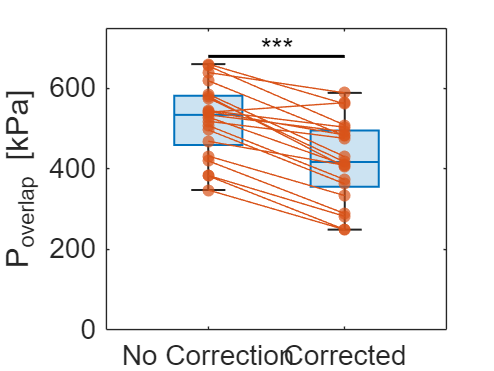


% Determine significance level and number of asterisks
if p_value < 0.001
    sig_str = '***'; % p < 0.001
elseif p_value < 0.01
    sig_str = '**';  % p < 0.01
elseif p_value < 0.05
    sig_str = '*';   % p < 0.05
else
    sig_str = 'n.s.'; % not significant
end

% Add significance indicator to the plot
y_max = max([no_corr, corr]) * 1.05; % Set y position above the highest data point
line([1, 2], [y_max*0.98, y_max*0.98], 'Color', 'k', 'LineWidth', 1.5); % Draw line between groups
if strcmp(sig_str, 'n.s.')
    text(1.5, y_max * 1.015, sig_str, ...
        'HorizontalAlignment', 'center', 'FontSize', 14);
else
    text(1.5, y_max * 1.005, sig_str, ...
            'HorizontalAlignment', 'center', 'FontSize', 14);
end

% title(['Data Summary (Human, V5, Total US Energy Delivered, p=', num2str(p_value), ')'], ...
%     'FontWeight','normal');

% hold on
% yline(18.2143, '-.b', 'Free-Field', 'FontSize', 14, 'LabelVerticalAlignment', 'bottom'); % for X_peak
% yline(19.2857, '-.b', 'Free-Field', 'FontSize', 14, 'LabelVerticalAlignment', 'bottom'); % for X_focus

box on;
hold off;


% f = gcf;
% exportgraphics(f,'./H-275 3D Simulations/subjects/results/V5/final/P_overlap_V5.png','Resolution',300);
% savefig('./H-275 3D Simulations/subjects/results/V5/final/P_overlap_V5.fig');

%%% V5 (Kranion data included)
% read measured data from worksheet
filename = './H-275 3D Simulations/Measured Data.xlsx';
sheets = sheetnames(filename);
lastSheet = sheets{end};
V5_L_Kranion_data = readtable(filename, 'Sheet', lastSheet, 'VariableNamingRule','preserve');

% clean raw data
nRows = height(V5_L_Kranion_data);
rowsToRemove = [];
for k = 5:7:nRows
    rowsToRemove = [rowsToRemove, k:min(k+2, nRows)];
end
V5_L_Kranion_data(rowsToRemove, :) = [];

% extract data into separate arrays
T = V5_L_Kranion_data;
conditions = unique(T{:,1});
varNames = T.Properties.VariableNames(2:14);
meanResults = cell(length(conditions), length(varNames));
stdResults  = cell(length(conditions), length(varNames));
for i = 1:length(conditions)
    cond = conditions{i};
    rows = strcmp(T{:,1}, cond);

    for j = 1:length(varNames)
        currentVar = varNames{j};
        dataMatrix = T{rows, currentVar};
        newVarName = matlab.lang.makeValidName([cond '_' currentVar]);
        assignin('base', newVarName, dataMatrix);

        % compute mean and std
        m = mean(dataMatrix);
        s = std(dataMatrix);
        meanResults{i,j} = m;
        stdResults{i,j}  = s;

        fprintf('%s - %s: %.2f ± %.2f\n', cond, currentVar, m, s);
    end
end

Corrected - X_focus/mm: 30.58 ± 6.82
Corrected - Y_focus/mm: 0.19 ± 0.43
Corrected - Z_focus/mm: -0.19 ± 0.43
Corrected - d_axial/mm: 29.51 ± 14.11
Corrected - d_lateral_y/mm: 3.51 ± 1.19
Corrected - d_lateral_z/mm: 3.80 ± 1.47
Corrected - V_focus/mm3: 285.24 ± 201.89
Corrected - P_avg/kPa: 432.54 ± 70.49
Corrected - V_overlap/mm3: 98.27 ± 43.69
Corrected - Overlap Rate/%: 5.36 ± 2.22
Corrected - P_overlap/kPa: 449.73 ± 66.70
Corrected - E_target/mJ: 7.58 ± 2.68
Corrected - X_peak/mm: 22.30 ± 6.57
Elements - X_focus/mm: 32.82 ± 5.30
Elements - Y_focus/mm: 0.29 ± 0.50
Elements - Z_focus/mm: -0.49 ± 0.56
Elements - d_axial/mm: 36.23 ± 10.92
Elements - d_lateral_y/mm: 3.60 ± 1.20
Elements - d_lateral_z/mm: 3.80 ± 1.39
Elements - V_focus/mm3: 359.82 ± 221.54
Elements - P_avg/kPa: 360.37 ± 54.68
Elements - V_overlap/mm3: 113.16 ± 33.11
Elements - Overlap Rate/%: 6.25 ± 2.06
Elements - P_overlap/kPa: 383.75 ± 62.81
Elements - E_target/mJ: 6.70 ± 2.52
Elements - X_peak/mm: 22.40 ± 7.10
Elemen

No_Correction = NoCorrection_d_axial_mm';
Ours = Corrected_d_axial_mm';
Kranion_Elements = Elements_d_axial_mm';
Kranion_Elements_Phase = Elements_Phase_d_axial_mm';

data = [No_Correction(:), ...
        Ours(:), ...
        Kranion_Elements(:), ...
        Kranion_Elements_Phase(:)];
groupNames = {'No Corr','kPR','KE','KE+Ph'};

% t-tests
[~, p_NoCorr_Ours]       = ttest(No_Correction, Ours)

p_NoCorr_Ours = 0.6745

[~, p_NoCorr_KranEl]     = ttest(No_Correction, Kranion_Elements)

p_NoCorr_KranEl = 0.1723

[~, p_NoCorr_KranElPhase]= ttest(No_Correction, Kranion_Elements_Phase)

p_NoCorr_KranElPhase = 6.9386e-05

[~, p_KranEl_Ours]       = ttest(Kranion_Elements, Ours)

p_KranEl_Ours = 0.0241

[~, p_KranEl_KranElPhase]= ttest(Kranion_Elements, Kranion_Elements_Phase)

p_KranEl_KranElPhase = 0.1571

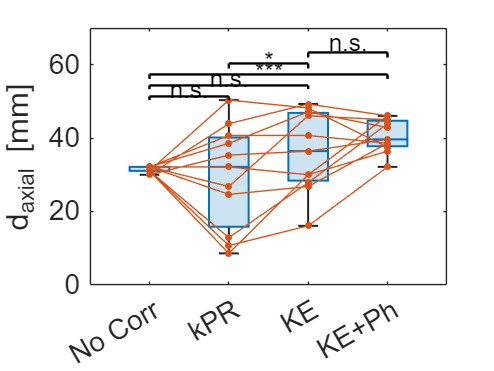


figure('Color','w'); 
hold on;

% Make a boxplot for the four conditions
% boxplot(data, 'Labels', {'No Corr','Ours','K.E.','K.E.+Ph'}, ...
%         'Symbol','o','OutlierSize',6);
boxchart(data, 'BoxWidth', 0.5);

% Add some jitter so the overlaid points don’t coincide exactly
% offset = linspace(-0.05, 0.05, size(data,1));
offset = zeros(1,size(data,1));

numMeasurements = size(data,1);
for i = 1:numMeasurements
    plot((1:4) + offset(i), data(i,:), '-o', ...
        'LineWidth', 0.5, ...
        'MarkerSize', 3.0, ...
        'Color',[0.8500 0.3250 0.0980], ...
        'MarkerFaceColor',[0.8500 0.3250 0.0980]);
end

% We can place these lines above the maximum data value (plus some space).
maxVal = max(data(:));
step = 3;  % vertical step between significance lines
startHeight = maxVal + 1;  % base line to start placing significance lines

%  (a) No Corr vs. Ours (positions 1 vs. 2)
addSigMarker(1, 2, startHeight, p_NoCorr_Ours);

%  (b) No Corr vs. Kranion Elements (positions 1 vs. 3)
addSigMarker(1, 3, startHeight+step, p_NoCorr_KranEl);

%  (c) No Corr vs. Kranion Elements+Phase (positions 1 vs. 4)
addSigMarker(1, 4, startHeight+2*step, p_NoCorr_KranElPhase);

%  (d) Kranion Elements vs. Ours (positions 3 vs. 2)
%      Typically you'd keep the order (2 < 3) or (3 < 2), but it doesn't matter
%      except visually. Let’s connect x=2 and x=3 in ascending order:
xA = min(2,3);
xB = max(2,3);
addSigMarker(xA, xB, startHeight+3*step, p_KranEl_Ours);

%  (c) Kranion Elements vs. Kranion Elements+Phase (positions 3 vs. 4)
addSigMarker(3, 4, startHeight+4*step, p_KranEl_KranElPhase);

% Tidy up the figure
set(gca, 'XTickLabel', groupNames);
set(gca, 'FontSize', 14);
% ylim([10, startHeight + 5*step]);
ylim([0 70]);
ylabel('d_{axial} [mm]');
% title('Comparison of 4 Correction Conditions (Human, V5, Peak Axial Position)');
box on;

hold on
% yline(18.2143, '-.b', 'Free-Field', 'FontSize', 14, 'LabelVerticalAlignment', 'bottom'); % for X_peak
% yline(19.2857, '-.b', 'Free-Field', 'FontSize', 14, 'LabelVerticalAlignment', 'bottom'); % for X_focus

hold off;

f = gcf;
exportgraphics(f,'./H-275 3D Simulations/subjects/results/V5/final/Kranion/N=11/d_axial_V5_Kranion.png','Resolution',300);

savefig('./H-275 3D Simulations/subjects/results/V5/final/Kranion/N=11/d_axial_V5_Kranion.fig');

function addSigMarker(x1, x2, yVal, pVal)
    % x1, x2: which box positions to connect
    % yVal: vertical level at which to place the line
    % pVal: p-value from the test
    
    % Plot a horizontal line
    plot([x1 x2], [yVal yVal], 'k-', 'LineWidth',1.2);
    
    % Plot short vertical ticks at each end
    tickHeight = 0.02*range(ylim);
    plot([x1 x1], [yVal yVal - tickHeight], 'k-', 'LineWidth',1.2);
    plot([x2 x2], [yVal yVal - tickHeight], 'k-', 'LineWidth',1.2);
    
    % Decide how many stars
    if pVal < 0.001
        starStr = '***';
    elseif pVal < 0.01
        starStr = '**';
    elseif pVal < 0.05
        starStr = '*';
    else
        starStr = 'n.s.';
    end
    
    % Place text in the middle
    if strcmp(starStr, 'n.s.')
        text(mean([x1,x2]), yVal + 0.035*range(ylim), starStr, ...
             'HorizontalAlignment','center','FontSize',12);
    else
        text(mean([x1,x2]), yVal + 0.010*range(ylim), starStr, ...
             'HorizontalAlignment','center','FontSize',12);
    end
end